# Bogolyubov’s averaging theorem applied to the Kramers-Henneberger Hamiltonian

Last modified by Cristel Chandre (June 22, 2021)

Comments? [cristel.chandre@univ-amu.fr ](mailto:cristel.chandre@univ-amu.fr)

We compare the Cauchy problems starting at $(x,p)=(x_0,p_0)$ (indicated by a black dot on figure 1) for the dynamics generated by the two Hamiltonians


$$H_2(x,p,t)=\frac{p^2}{2}-\frac{1}{\sqrt{(x+q\cos\omega t)^2+a^2}},$$



$$\overline{H}_2(x,p)=\frac{p^2}{2}-\frac{1}{2\pi}\int_0^{2\pi} \frac{1}{\sqrt{(x+q\cos\phi)^2+a^2}} {\rm d}\phi,$$


where $q=\frac{E_0}{\omega^2}$ and $E_{\rm KH}\equiv \overline{H}_2(x_0,p_0) <0$. We estimate the differences $\sigma_x$(red line on figure 2) and $\sigma_p$(red dash-dotted line on figure 2) given by


$$\sigma_x = \max_{t\leq t_{\rm max}} \vert x(t)-\overline{x}(t)\vert / q, \\
\sigma_p = \max_{t\leq t_{\rm max}} \vert p(t)-\overline{p}(t)\vert /(E_0/\omega),$$


where ${\bf z}(t)=(x(t),p(t))$ is the trajectory for $H_2$ (represented by a red curve on figure 1), and ${\bf u}(t)=(\overline{x}(t),\overline{p}(t))$the trajectory for $\overline{H}_2$ (represented by a blue curve on figure 1).

**Reference:** E. Floriani, J. Dubois, C. Chandre, *Bogolyubov’s averaging theorem applied to the Kramers-Henneberger Hamiltonian*, preprint (2021)

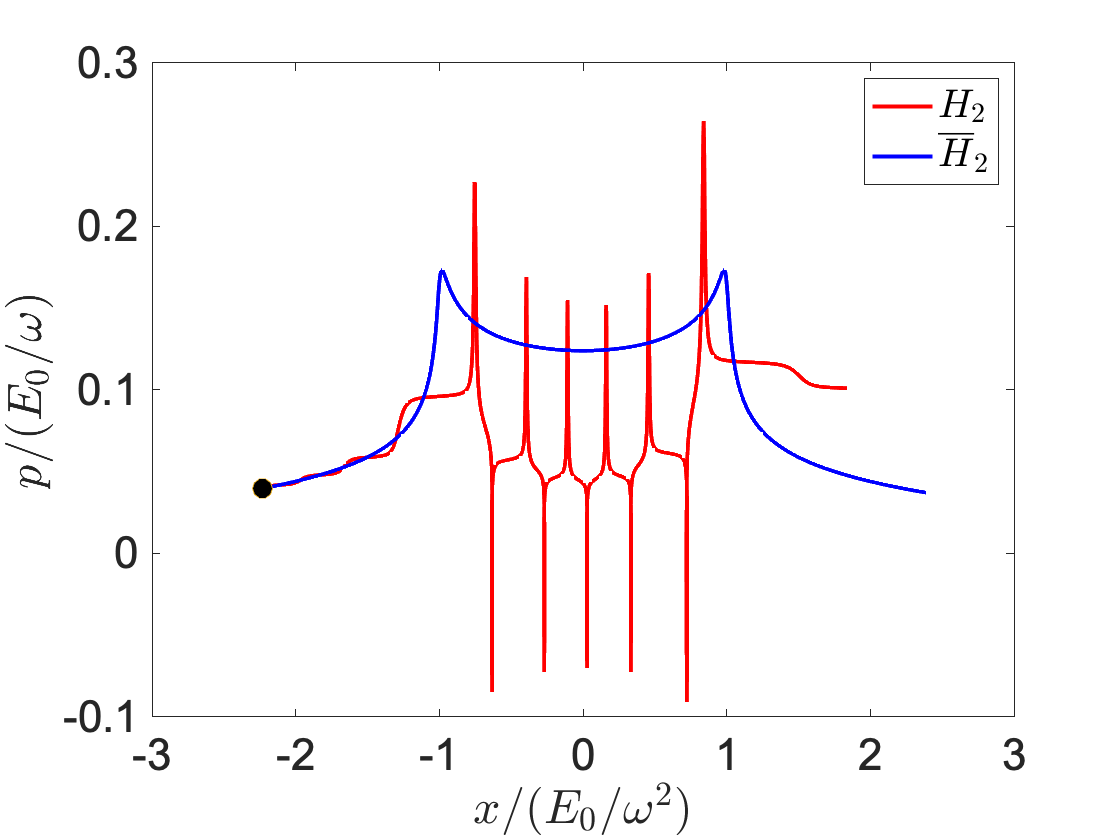

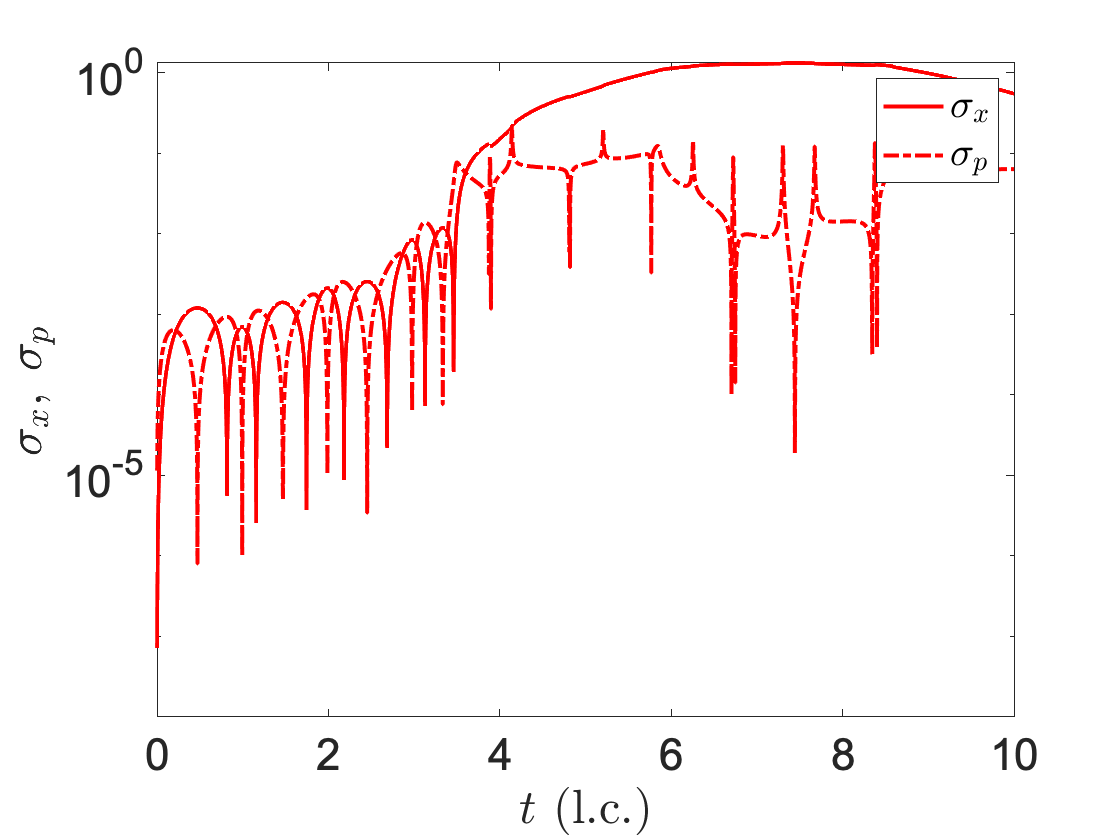

I = 1e15;
omega = 0.0584;
a = 1;
ncycle = 10;

h = 1e-7;
N = 5000;

E0 = sqrt(I/3.5e16);
qr = E0/omega^2;
pr = E0/omega;
T = 2*pi/omega;
EKHmin = -max(integral(@(phi) 1./sqrt((linspace(0, 2*qr, N)+qr*cos(phi)).^2+a^2), 0, 2*pi, 'ArrayValued', true)/(2*pi));

x0 =-2.2302* qr;
EKH =-0.0035;

options = odeset('AbsTol', h, 'RelTol', h);
tspan = linspace(0, ncycle*T, N);
p0 = sqrt(2*(EKH+integral(@(phi) 1./sqrt((x+qr*cos(phi)).^2+a^2), 0, 2*pi)/(2*pi)));

if imag(p)==0
    
    [~, z] = ode45(@(t,y) [y(2); -(y(1)+qr*cos(omega*t))./((y(1)+qr*cos(omega*t)).^2+a^2).^1.5], tspan, [x0, p0], options);
    [~, u] = ode45(@(t,y) [y(2); -integral(@(phi) (y(1)+qr*cos(phi))./((y(1)+qr*cos(phi)).^2+a^2).^1.5, 0, 2*pi)/(2*pi)], tspan, [x0, p0], options);
    
    figure(1), clf;
    p1 = plot(z(:,1)/qr, z(:,2)/pr, 'r', 'LineWidth', 2);
    hold(gca, 'on')
    p2 = plot(u(:,1)/qr, u(:,2)/pr, 'b', 'LineWidth', 2);
    p3 = plot(x0/qr, p0/pr, 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
    xlabel('$x/(E_0/\omega^2)$', 'Interpreter', 'latex', 'FontSize', 25);
    ylabel('$p/(E_0/\omega)$', 'Interpreter', 'latex', 'FontSize', 25);
    set(gca, 'FontSize', 22, 'FontName', 'Arial', 'Box', 'on')
    legend([p1 p2], {'$H_2$', '$\overline{H}_2$'}, 'Interpreter', 'latex')
    
    figure(2), clf;
    semilogy(tspan/T, abs(z(:,1)-u(:,1))/qr, 'r-', 'LineWidth', 2);
    hold(gca, 'on')
    semilogy(tspan/T, abs(z(:,2)-u(:,2))/pr, 'r-.', 'LineWidth', 2);
    xlabel('$t$ (l.c.)', 'Interpreter', 'latex', 'FontSize', 25);
    ylabel('$\sigma_x, \; \sigma_p$', 'Interpreter', 'latex', 'FontSize', 25);
    set(gca, 'FontSize', 22, 'FontName', 'Arial', 'Box', 'on')
    xlim([0 ncycle])
    legend('$\sigma_x$', '$\sigma_p$', 'Interpreter', 'latex')
    
end

Copyright (c) 2021 Cristel Chandre.

All rights reserved.

Redistribution and use in source and binary forms are permitted provided that the above copyright notice and this paragraph are duplicated in all such forms and that any documentation, advertising materials, and other materials related to such distribution and use acknowledge that the software was developed by the CNRS. The name of the CNRS may not be used to endorse or promote products derived from this software without specific prior written permission.

THIS SOFTWARE IS PROVIDED "AS IS" AND WITHOUT ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, WITHOUT LIMITATION, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE.